## Solar Tracker Position Prediction in Simulink via Machine Learning

### Load and Prepare Input Data

Load the Machine Learning models from `model_comparison_results.mat` file. To generate it, run the training process using the `ML_solar_tracker.m` script located in the `Machine_Learning_model` folder. All necessary data is provided in the repository; simply run the script to proceed.

*Note: Depending on your system, the training process may take several minutes.*

if isfile("Machine_Learning_model/model_comparison_results.mat")
    model_data = load("Machine_Learning_model/model_comparison_results.mat");
else
    disp("The file model_comparison_results.mat does not exist.")     
end

Load solar position and environmental data for prediction.

test_data = readtable("data_for_simulation/Cloudy_test_data_30m.csv");

Calculation of additional time variables

hour_decimal = test_data.Hour + test_data.Minute/60;
day_of_year = day(datetime(test_data.year, test_data.month, test_data.day), 'dayofyear');
hour_sin = sin(2*pi*hour_decimal/24);
hour_cos = cos(2*pi*hour_decimal/24);

#### Select the trained model

Model_selection = "RF";

### Input Vectors and Prediction of Solar Tracker Position

Use trained models to predict tilt and azimuth angles based on time and environmental conditions.

switch Model_selection
    case "RF"        
        % Input vectors
        feature_names_az = model_data.rf_results.models.az_var_names;
        feature_names_ti = model_data.rf_results.models.ti_var_names;
        X_az = input_features(feature_names_az, test_data);
        X_ti = input_features(feature_names_ti, test_data);
        % Load RF models
        rf_azimuth = model_data.rf_results.models.azimuth;
        rf_tilt = model_data.rf_results.models.tilt;
        % Predict position
        pred_azimuth = predict(rf_azimuth, X_az);
        pred_tilt = predict(rf_tilt, X_ti);
    case "MLP"       
        % Input vector       
        feature_names_az = model_data.dl_results.models.az_var_names;
        feature_names_ti = model_data.dl_results.models.ti_var_names;
        X_az = input_features(feature_names_az, test_data);
        X_ti = input_features(feature_names_ti, test_data);
        train_mu_az = model_data.dl_results.normalization.mu_az;
        train_sigma_az = model_data.dl_results.normalization.sigma_az;
        train_mu_ti = model_data.dl_results.normalization.mu_ti;
        train_sigma_ti = model_data.dl_results.normalization.sigma_ti;
        X_az_norm = normalize(X_az, 'center', train_mu_az, 'scale', train_sigma_az);
        X_ti_norm = normalize(X_ti, 'center', train_mu_ti, 'scale', train_sigma_ti);
        % Load MLP models
        dl_azimuth = model_data.dl_results.models.azimuth;
        dl_tilt = model_data.dl_results.models.tilt;
        % Predict position
        pred_azimuth = predict(dl_azimuth, X_az_norm);
        pred_tilt = predict(dl_tilt, X_ti_norm);
end

### Positioning conditions and motor signals

Movement of the panels is conditioned according to nighttime hours and physical limitations.

panel_azimuth = zeros(length(pred_azimuth), 1);
panel_tilt = zeros(length(pred_azimuth), 1);

idx_sunlight = test_data.zenith_deg < 90;
idx_night = test_data.zenith_deg >= 90;
% Index for GHI = 0 during the day
idx_dark = test_data.zenith_deg < 90 & test_data.GHI == 0;

% Assigning values for daytime hours
panel_azimuth(idx_sunlight) = pred_azimuth(idx_sunlight);
panel_tilt(idx_sunlight) = pred_tilt(idx_sunlight);

% Resting position for nighttime hours (adjust according to the location of your
% system)
panel_azimuth(idx_night) = 80; 
panel_tilt(idx_night | idx_dark) = 29;   % Angle for resting position

% Limit physical ranges of the system
panel_tilt = max(0, min(70, panel_tilt));    % 0° to 70°

Calculating the steps that the stepper motors must take

% Stepper motor precision
grades_for_step_az = 1.8;  % 200 step/revolution motor = 1.8°/step
grades_for_step_ti = 1.8;  % 200 step/revolution motor = 1.8°/step

% Convert to motor steps
azimuth_steps = round(panel_azimuth / grades_for_step_az);
tilt_steps = round(panel_tilt / grades_for_step_ti);

% Simulation time
t_sim = (0 : length(azimuth_steps) - 1)';

Plotting the azimuth and tilt angles of the solar panel

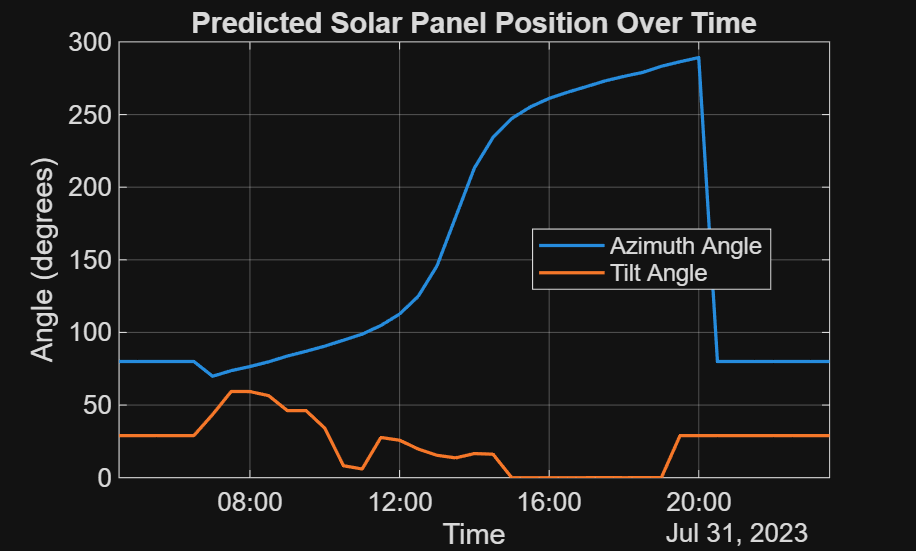

timeVect = datetime(test_data.year, test_data.month, test_data.day, test_data.Hour, test_data.Minute, 0);
timeVect.TimeZone = 'America/New_York';

figure();
plot(timeVect, panel_azimuth, 'LineWidth', 1.5)
hold on
plot(timeVect, panel_tilt, 'LineWidth', 1.5)
hold off

title('Predicted Solar Panel Position Over Time')
xlabel('Time')
ylabel('Angle (degrees)')
legend('Azimuth Angle', 'Tilt Angle', 'Location', 'best')
grid on
xlim("tight")
set(gca, 'FontSize', 12)

Solar tracker working with astronomical sun position

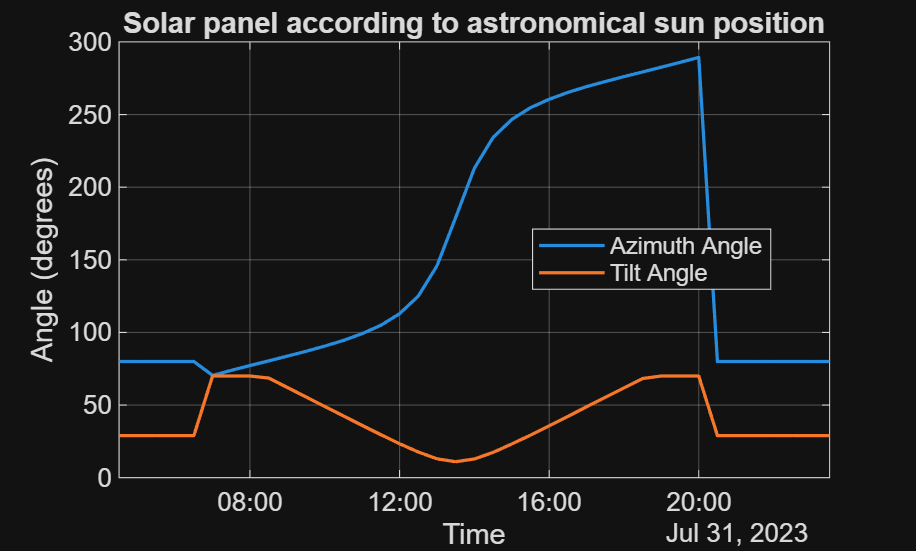

panel_sun_az = zeros(length(pred_azimuth), 1);
panel_sun_ti = zeros(length(pred_azimuth), 1);

panel_sun_az(idx_night) = 80;
panel_sun_az(idx_sunlight) = round(test_data.azimuth_deg(idx_sunlight),1);

panel_sun_ti(idx_night) = 29;
panel_sun_ti(idx_sunlight) = round(test_data.zenith_deg(idx_sunlight),1);

panel_sun_ti = max(0, min(70, panel_sun_ti));

figure();
plot(timeVect, panel_sun_az, 'LineWidth', 1.5)
hold on
plot(timeVect, panel_sun_ti, 'LineWidth', 1.5)
hold off

title('Solar panel according to astronomical sun position')
xlabel('Time')
ylabel('Angle (degrees)')
legend('Azimuth Angle', 'Tilt Angle', 'Location', 'best')
grid on
xlim("tight")
set(gca, 'FontSize', 12)


timeVect.Format = "uuuu-MM-dd HH:mm:ssZZZZZ"; % For PVlib
% Save panel position
prediction_results = table(timeVect, panel_azimuth, panel_tilt, panel_sun_az, panel_sun_ti, ...
    test_data.DNI, test_data.DHI, test_data.GHI,...
    'VariableNames',{'Datetime', 'Predicted_azimuth', 'Predicted_tilt', 'Astro_azimuth', 'Astro_tilt', ...
    'DNI', 'DHI', 'GHI'});
writetable(prediction_results, "prediction_results.csv"); % For irradiance_for_prediction.py

#### Create time series

% Signal 1: Azimuth angle
azimuth_input = timeseries(azimuth_steps, t_sim);
azimuth_input.Name = 'Azimuth_steps';

% Signal 2: Tilt angle
tilt_input = timeseries(tilt_steps, t_sim);
tilt_input.Name = 'Tilt_steps';

### Simulink Model to Predict Panel Position

Load the Simulink model WormAndGearConstraint.slx.

modelName = 'WormAndGearConstraint';
open_system(modelName);

Running the Simulink Model with Custom Stop Time

simParams = Simulink.SimulationInput(modelName);
simParams = simParams.setModelParameter( StopTime = string(t_sim(end)) );
sim(simParams);

### Comparison between irradiance values produced by Machine Learning and by astronomical solar tracking.

Modify this if you want to run the comparison code from MATLAB, or you can open another development environment.

If you want to execute the code from MATLAB, you must use a compatible version of Python ([https://la.mathworks.com/support/requirements/python-compatibility.html](https://la.mathworks.com/support/requirements/python-compatibility.html)).

It is recommended to install PVlib in a virtual environment. For more information on how to install PVlib, visit:

[https://pvlib-python.readthedocs.io/en/stable/index.html](https://pvlib-python.readthedocs.io/en/stable/index.html).

You also need to install the Matplotlib library inside the virtual environment.

Once you have Python, PVlib and Matplotlib installed, you must do the following:

- Locate the files `tcl86t.lib` and `tk86t.lib` inside the Python installation folder, and copy their paths into the following lines of code:

pyTCL = "...\Python312\tcl\tcl86t.lib"; % tcl86t.lib full path
pyTK = "...\Python312\tcl\tk86t.lib";   % tk86t.lib full path
setenv('TCL_LIBRARY', pyTCL);
setenv('TK_LIBRARY', pyTK);

- Select the `irradiance_for_prediction.py` file in the **Run Python Code** section below.

- If you want to simulate a different location than the one in this example, you must modify the `irradiance_for_prediction.py` code by changing the coordinates, altitude, temperature, time zone, and pressure. Keep in mind that this also means you must train a new model using data corresponding to the new location.

% Python code input
pycode = [...
"irradiance_for_prediction.py "...
];

pyrunfile(pycode)
% Clear temporary variables from workspace and from Python
clear pycode;

### Energy Storage Comparison

pred_irradiance = readtable("ml_vs_astronomical_comparison_results.csv", "Delimiter",",");
t_f = 0.01;
t_sim2 = t_sim*t_f;
run("SolarPVMPPTBoostData.mlx");

***********************************************************************************************
****                PV Plant Parameters for the Specified Solar Panel                 ****
***********************************************************************************************
*** Power rating input from the user  =  1.00 kW 
*** Minimum number of panel required per string  =  1 
*** Maximum number of panel connected per string without reaching maximum voltage  =  1 
*** Minimum power rating of the solar PV plant  =  0.33 kW 
*** Maximum power possible per string without reaching maximum DC voltage  =  0.33 kW 
*** Actual number of panel per string  =  1 
*** Number of strings connected in parallel  =  3 
*** Actual solar PV plant power  =  0.99 kW
***********************************************************************************************


open_system("SolarPVMPPTBoost");

cases = {'ML', 'SPA'};
results = struct();

for i = 1:length(cases)
    case_name = cases{i};
    
    % Load the corresponding profile
    switch case_name
        case 'ML'
            irradiance = timeseries(pred_irradiance.ml_poa_global, t_sim2);
        case 'SPA'
            irradiance = timeseries(pred_irradiance.astro_poa_global, t_sim2);
    end
        
    assignin('base', 'irradiance_input', irradiance);    
    sim('SolarPVMPPTBoost');

    % Save results
    results.(case_name) = getElement(SolarPVMPPTBoost_logDB,'SOC').Values;
end

State of Charge comparison (Machine Learning vs SPA)

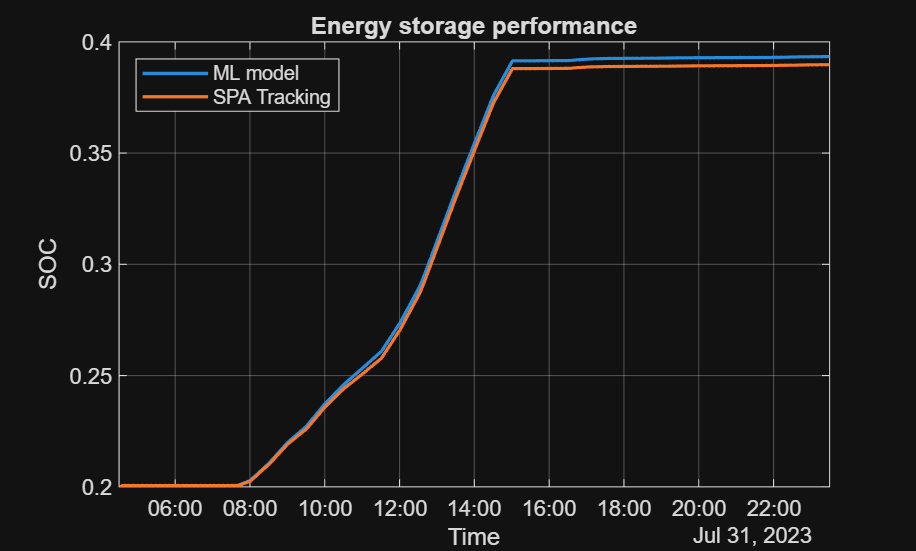

t_interval = 2; % 1 for 60 min; 2 for 30 min; 6 for 10 min; 12 for 5 min
t_ml = timeVect(1) + hours((results.ML.Time./t_f)./t_interval); 
t_spa = timeVect(1) + hours((results.SPA.Time./t_f)./t_interval);
plot(t_ml, results.ML.Data, 'LineWidth', 1.5)
hold on
plot(t_spa, results.SPA.Data, 'LineWidth', 1.5)
legend('ML model', 'SPA Tracking', 'Location', 'northwest')
hold off
xlim('tight')
ylabel('SOC')
xlabel('Time')
title('Energy storage performance')
grid on


energy_hours = timeVect(test_data.GHI>0);
idx_ml_soc = t_ml >= energy_hours(1) & t_ml <= energy_hours(end);
idx_spa_soc = t_spa >= energy_hours(1) & t_spa <= energy_hours(end);
ML_soc = results.ML.Data(idx_ml_soc);
SPA_soc = results.SPA.Data(idx_spa_soc);
soc_end = (ML_soc(end) - SPA_soc(end))/SPA_soc(end) * 100;
fprintf("The difference in battery SOC was %0.2f %% (ML model - SPA tracking)", soc_end)

The difference in battery SOC was 0.94 % (SPA tracking - ML model)

#### Auxiliary function

function X = input_features(names, test_data)
    X = [];
    for i = 1:length(names)
        var_name = names{i};    
        
        if evalin('base', ['exist(''' var_name ''', ''var'')'])            
            current_vector = evalin('base', var_name);            
            X = [X, current_vector];
        else
            current_vector = table2array(test_data(:,var_name));
            X = [X, current_vector];
        end
    end
end